## All Rt for US states

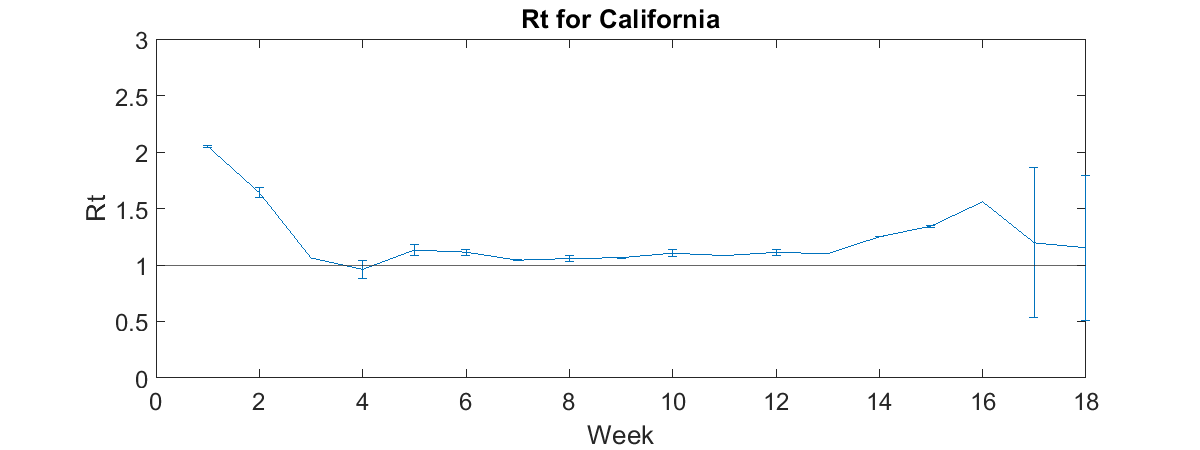

Rt_tab = readtable('../results/scores/us_Rt_num.csv');
Rt_us = Rt_tab{2:end, 3:end};
countries = Rt_tab{2:end, 2};
Rt_tab = readtable('../results/scores/us_Rt_conf.csv');
Rt_dev = Rt_tab{2:end, 3:end};
figure('DefaultAxesFontSize',18);
set(gcf,'position',[10,10,1200,450])

Tx = datetime(2020, 1, 21)+caldays(52:7:52+7*(size(Rt_us, 2)-1));
datecols= datestr(Tx, 'yyyy-mm-dd');
datecols = cellstr(datecols);

%boxplot(Rt_us, datecols,'PlotStyle','compact', 'symbol','');
cid = 3; errorbar((Rt_us(cid, :)), Rt_dev(cid, :));
yline(1);
title('Rt for California');
xlabel('Week');
ylabel('Rt');
ylim([0, 3]);

## Model based IR

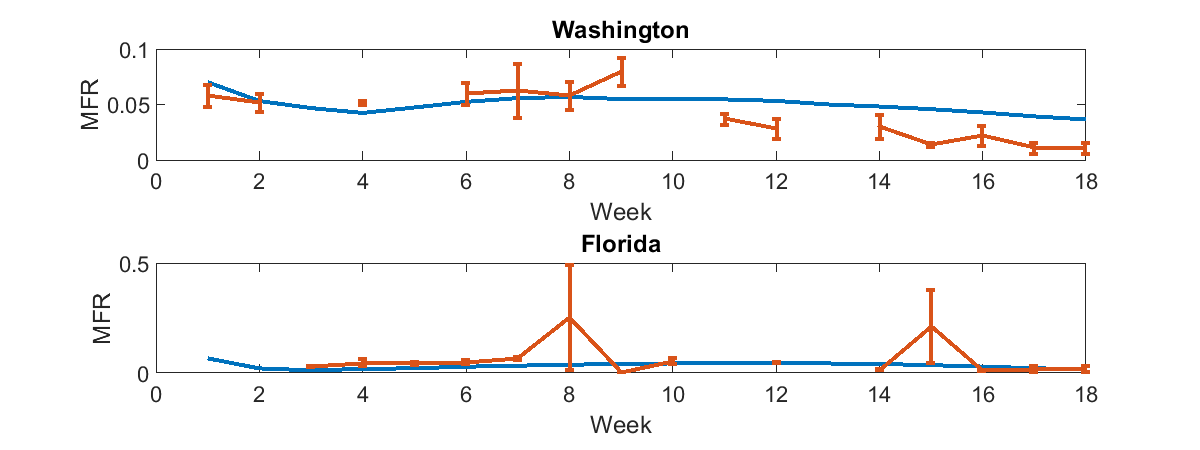

Rt_tab = readtable('../results/scores/us_MFR_num.csv');
MFR_us = Rt_tab{2:end, 3:end};
Rt_tab = readtable('../results/scores/us_MFR_conf.csv');
MFR_dev = Rt_tab{2:end, 3:end};

figure('DefaultAxesFontSize',18);
set(gcf,'position',[10,10,1200,450])

tickdays = 50:7:50+7*(size(Rt_us, 2)-1);
Tx = datetime(2020, 1, 21)+caldays(tickdays);
datecols= datestr(Tx, 'yyyy-mm-dd');
datecols = cellstr(datecols);

%boxplot(Rt_us, datecols,'PlotStyle','compact', 'symbol','');
subplot(2, 1, 1); 
cid = 1; 
plot(deaths(cid, tickdays)./data_4(cid, tickdays),'LineWidth',3); hold on;
errorbar(MFR_us(cid, :), MFR_dev(cid, :), 'LineWidth',3); hold off;
title(countries{cid})
xlabel('Week');
ylabel('MFR');

subplot(2, 1, 2); 
cid = 11; 
plot(deaths(cid, tickdays)./data_4(cid, tickdays),'LineWidth',3); hold on;
errorbar(MFR_us(cid, :), MFR_dev(cid, :), 'LineWidth',3); hold off;
title(countries{cid})
xlabel('Week');
ylabel('MFR');

## Rt for US

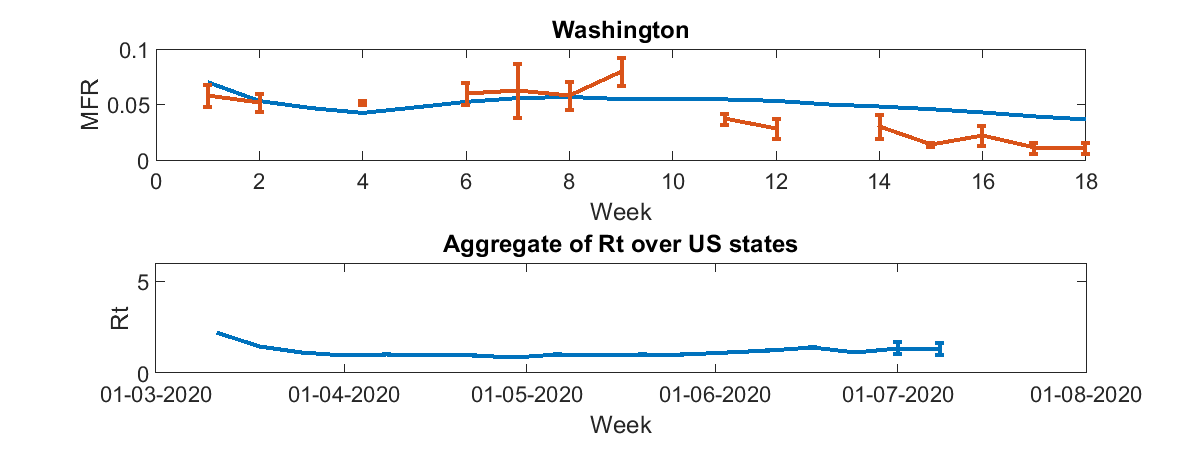

Rt_tab = readtable('../results/scores/global_Rt_num.csv');
Rt_dev_tab = readtable('../results/scores/global_Rt_conf.csv');
Rt_global = Rt_tab{2:end, 3:end};
Rt_global_dev = Rt_dev_tab{2:end, 3:end};
%figure('DefaultAxesFontSize',14);
set(gcf,'position',[10,10,1200,450])
Tx = datenum(Tx);
errorbar(Tx, Rt_global(156, :), Rt_global_dev(156, :), 'LineWidth', 3);
datetick('x', 'dd-mm-yyyy')

%boxplot(Rt_scores, datecols,'PlotStyle','compact', 'symbol','');

title('Aggregate of Rt over US states');
xlabel('Week');
ylabel('Rt');
ylim([0, 6]);
%legend({'True', 'S', 'NL(i)', 'NL(f)', 'F'}, 'Location','northeast', 'Interpreter', 'latex');
hold off;

## Rt aggregated over countries

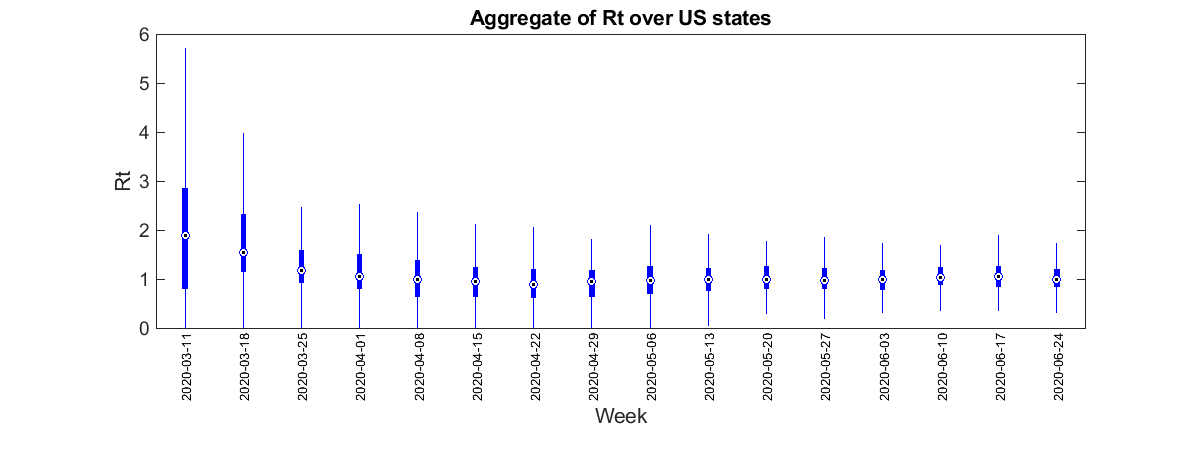

figure('DefaultAxesFontSize',14);
set(gcf,'position',[10,10,1200,450])

boxplot(Rt_global, datecols,'PlotStyle','compact', 'symbol','');

title('Aggregate of Rt over US states');
xlabel('Week');
ylabel('Rt');
ylim([0, 6]);
%legend({'True', 'S', 'NL(i)', 'NL(f)', 'F'}, 'Location','northeast', 'Interpreter', 'latex');
hold off;